In the name of allah

# Linear Control Systems

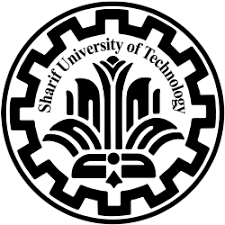

Hw 06

ali sadeghian 400101464

Fall 1402

# Theory Assignments

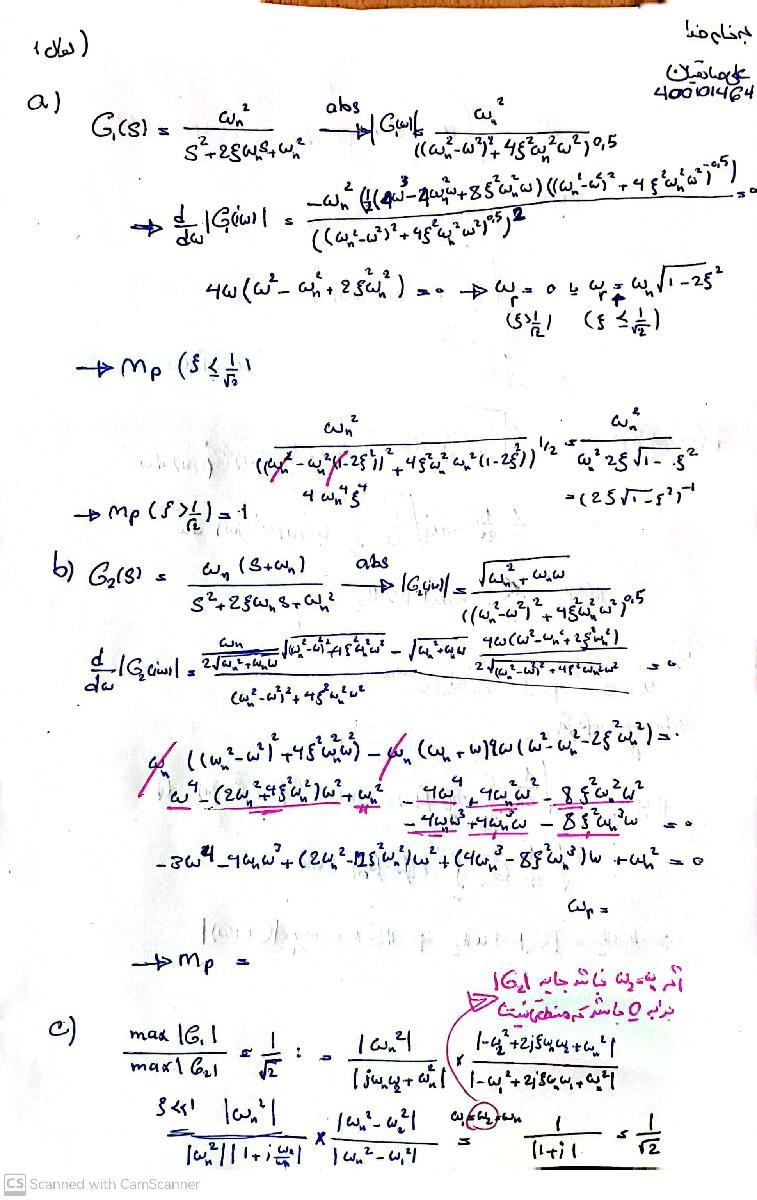

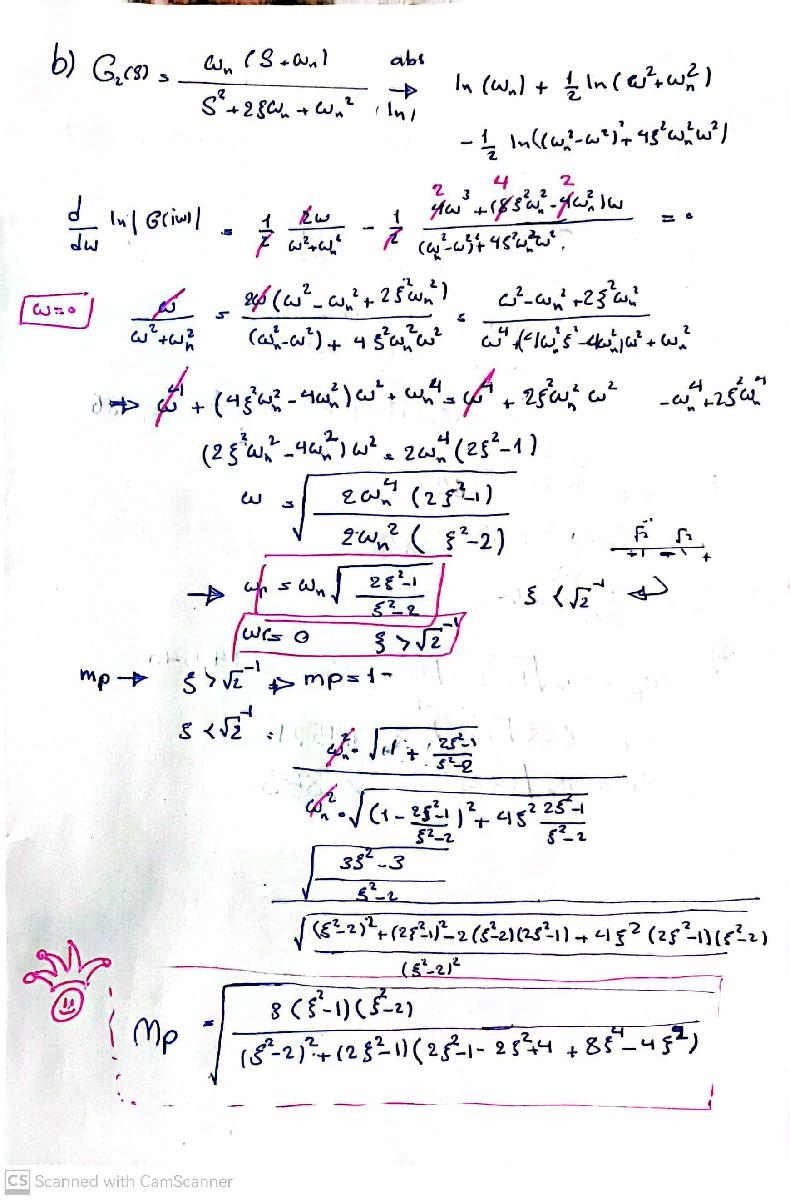

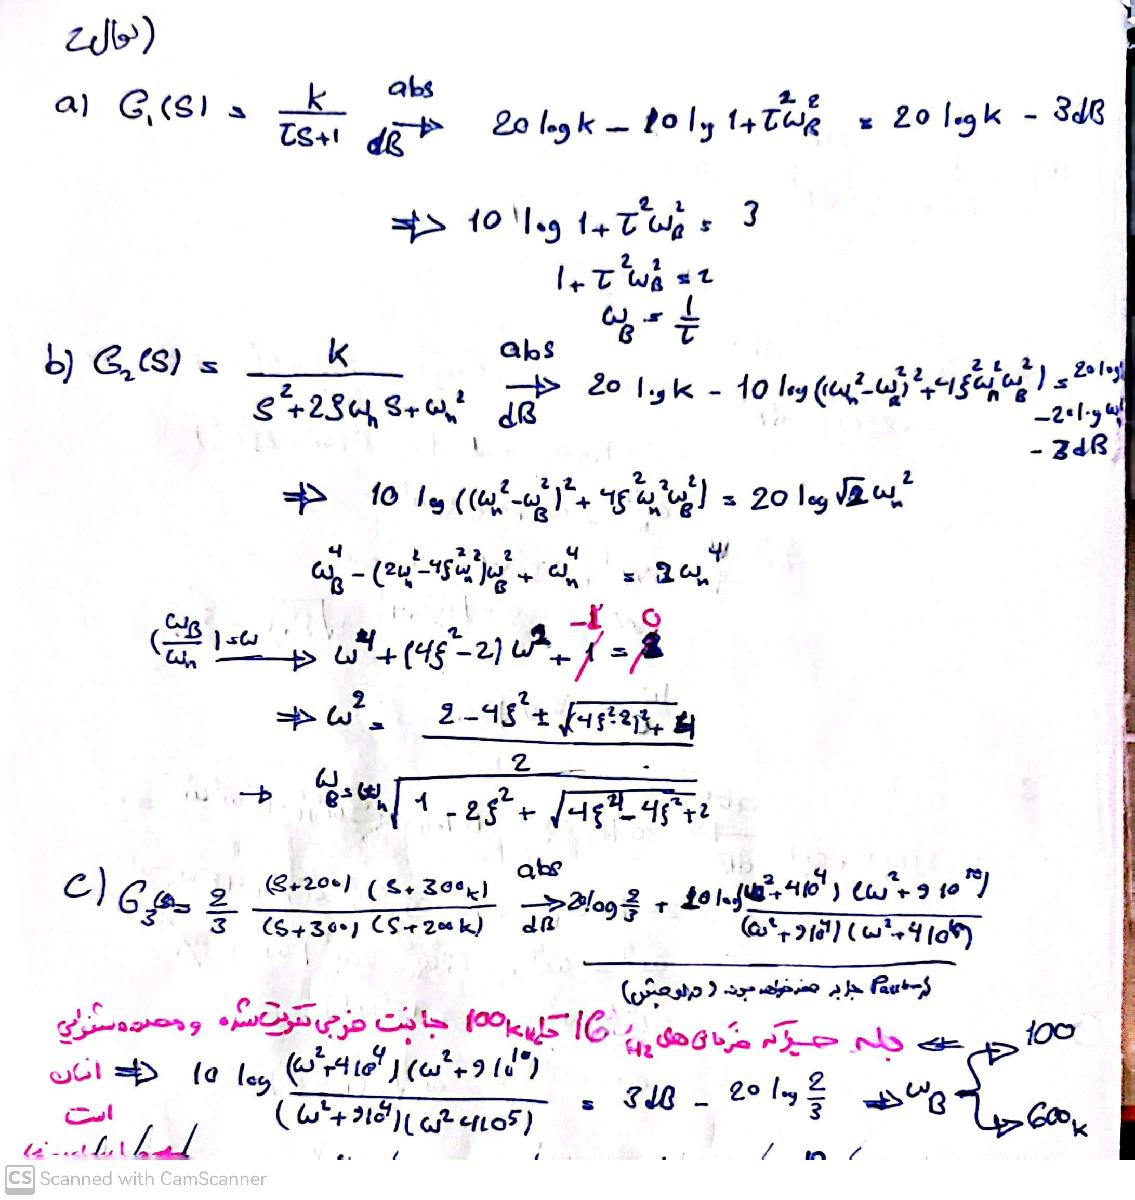

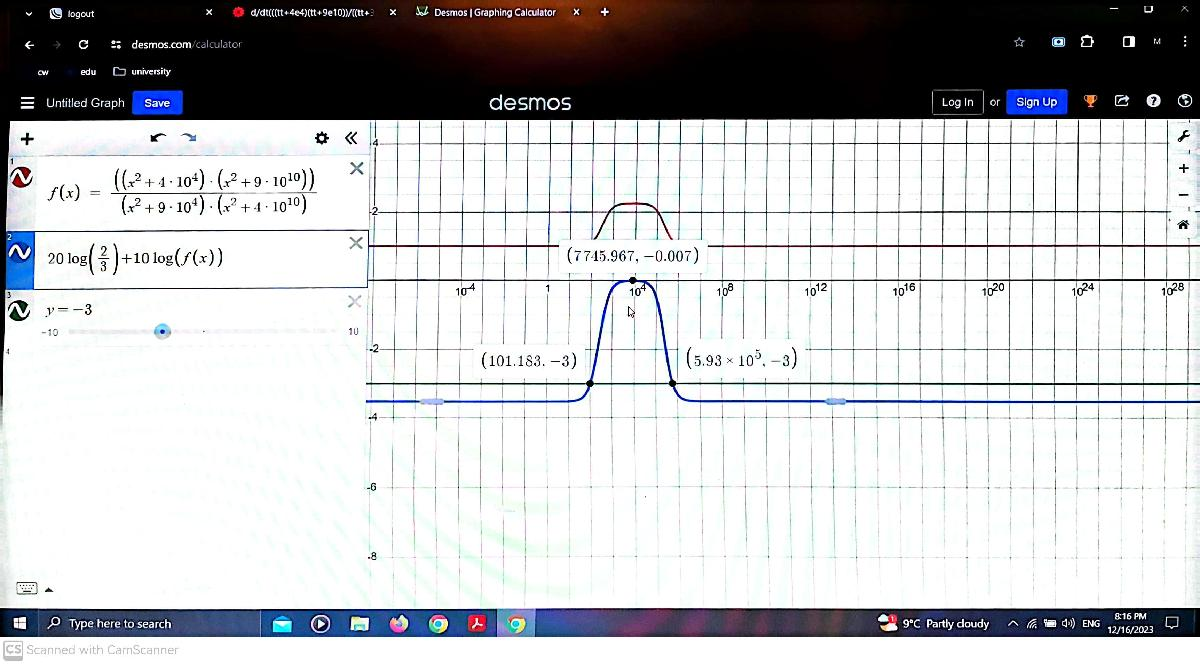

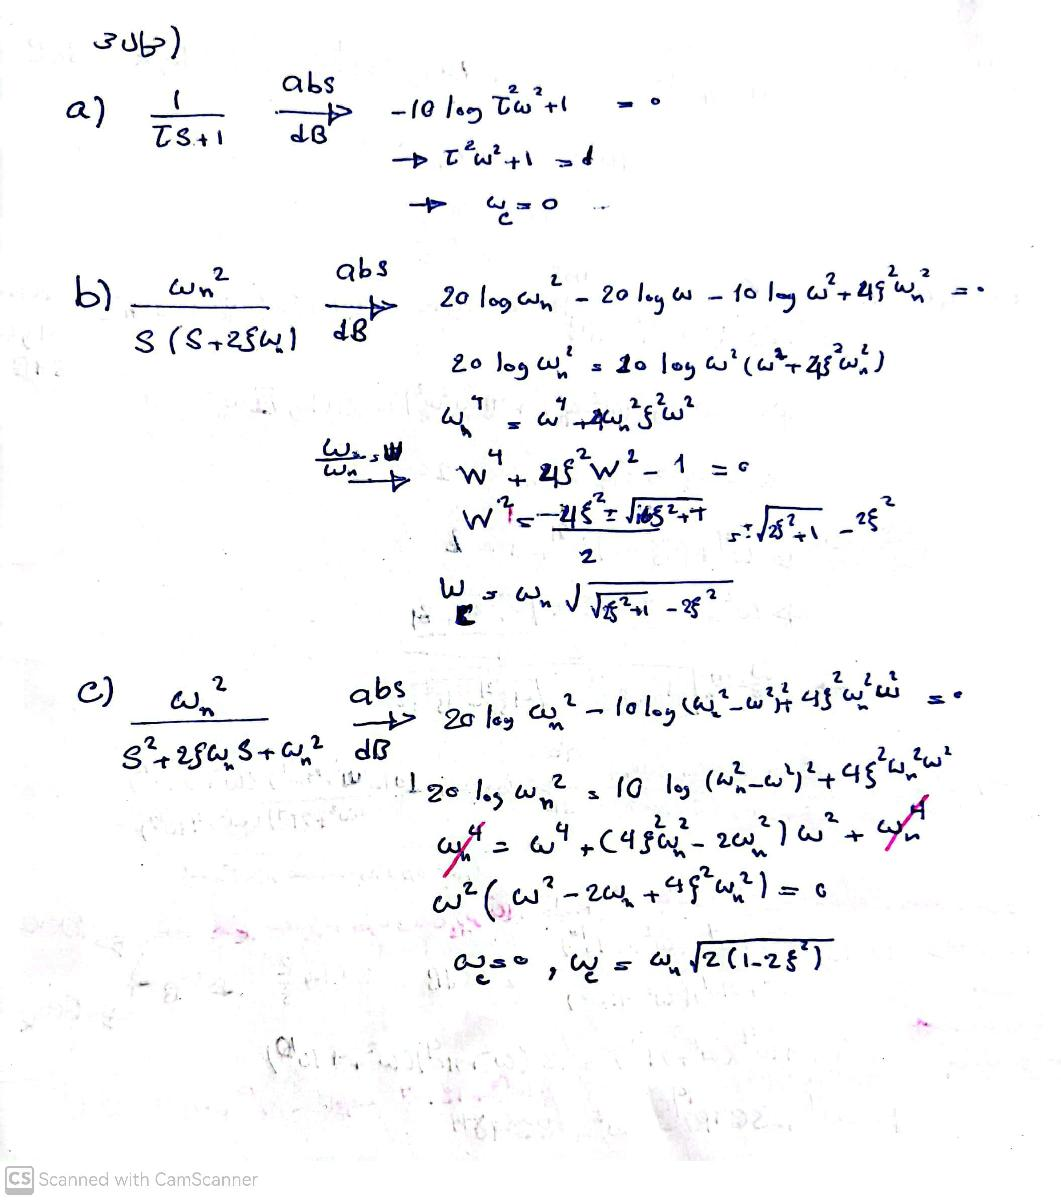

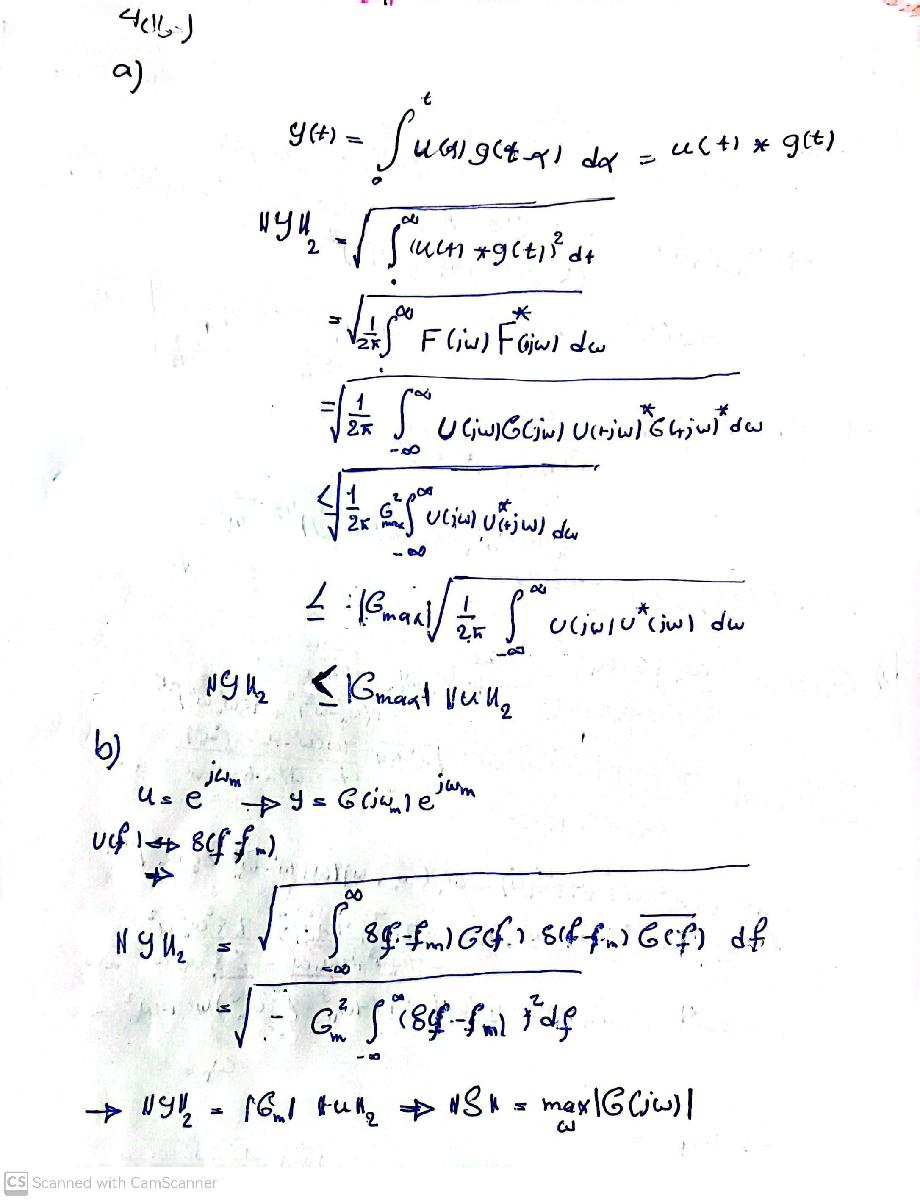

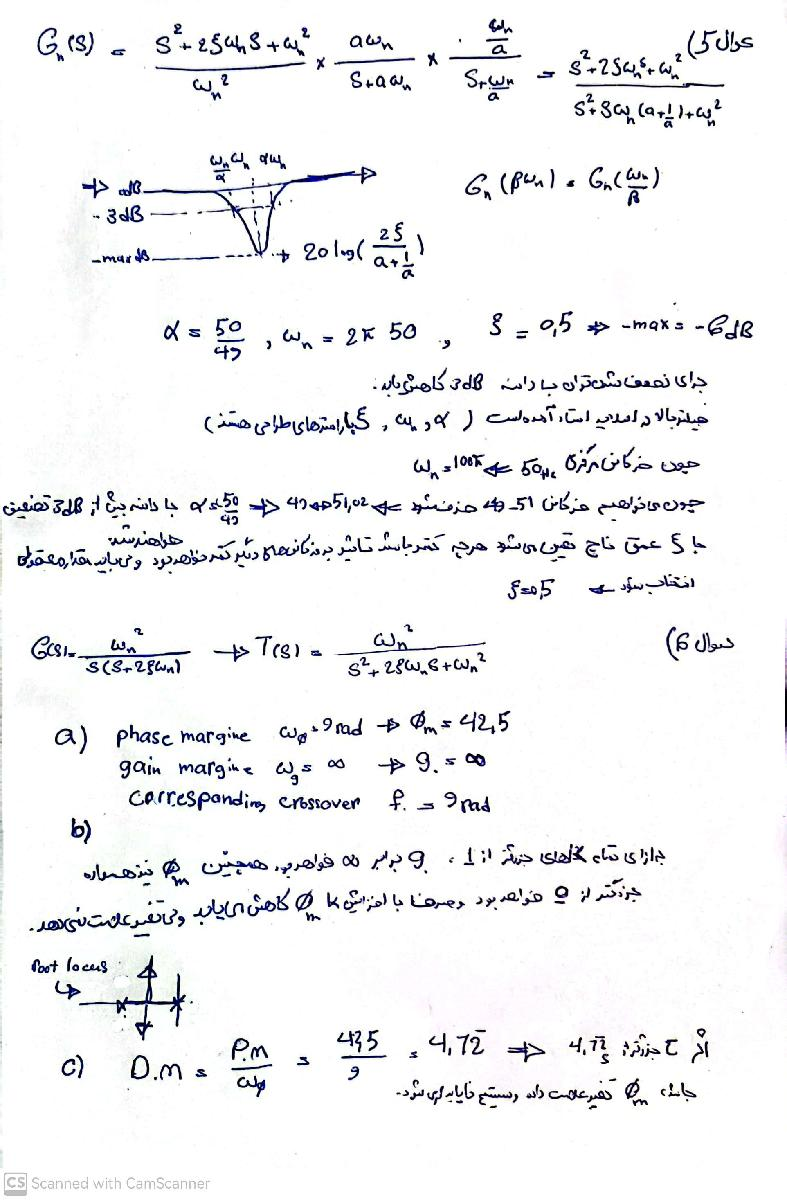

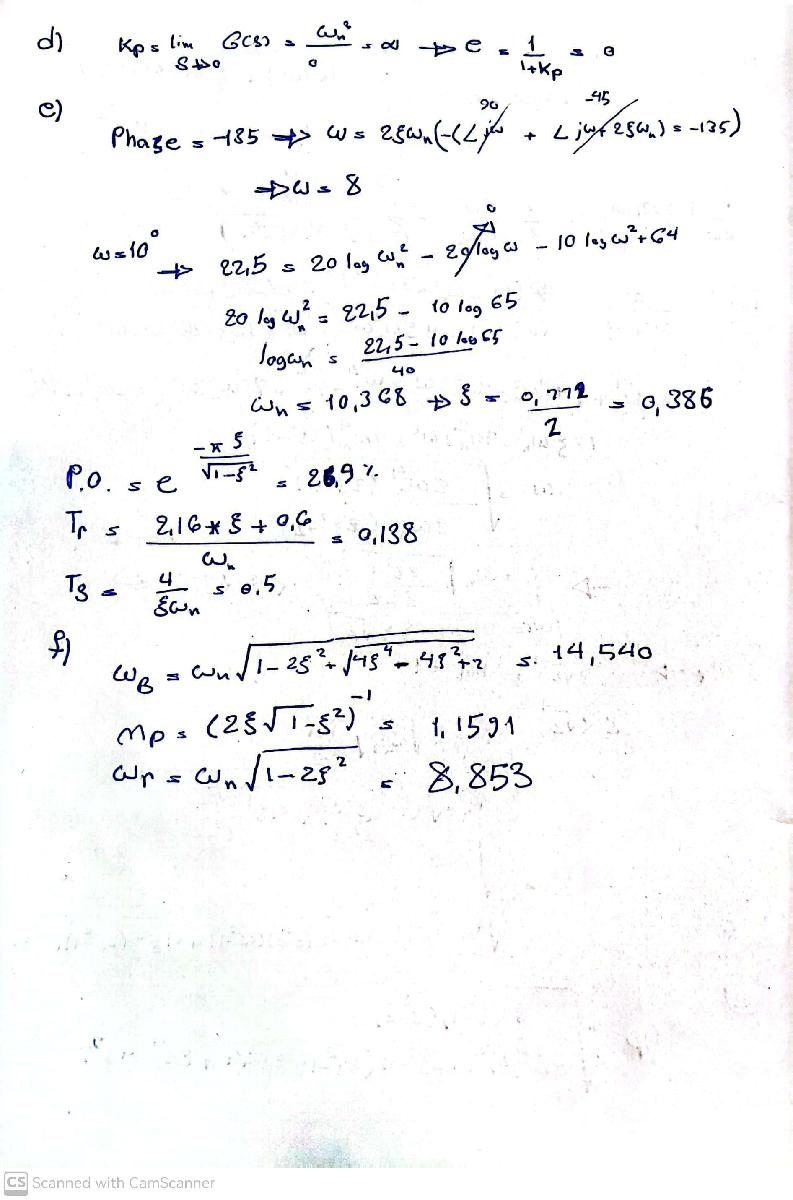

clc 
clear all
close all

# MATLAB Assignment

# 7 Bode Diagram Plot

## a)

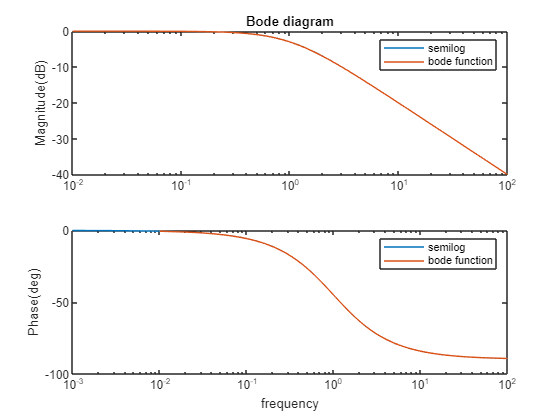

w = logspace(-3,2,200);

s = tf("s");
Gb = 1/(s+1);
syms s
Gl = @(s) 1./(s+1);
Gl = Gl(1i*w);


[mag,pha,wout]=bode(Gb);

Glm = 20*log10(abs(Gl));
Glp = atan2d(imag(Gl),real(Gl));

magi = 20*log10(mag(1,1,1));
for i=2:size(mag,3)
    magi = [magi,20*log10(mag(1,1,i))];
end
phai = pha(1,1,1);
for i=2:size(pha,3)
    phai = [phai,pha(1,1,i)];
end

subplot(2,1,1)
semilogx(w,Glm,wout,magi)
xlim([0.01 100])

ylabel("Magnitude(dB)")
title("Bode diagram")
legend("semilog","bode function")

subplot(2,1,2)
semilogx(w,Glp,wout,phai)
xlabel("frequency")
ylabel("Phase(deg)")
legend("semilog","bode function")

## b)

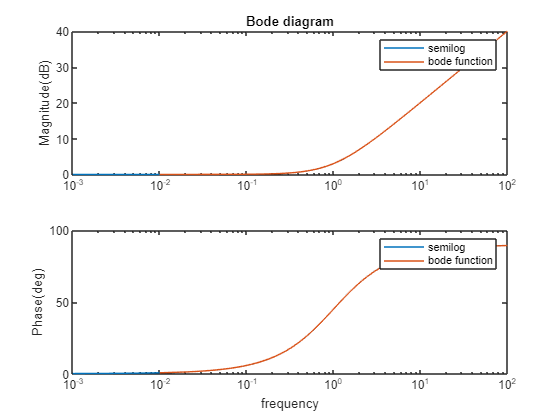

s = tf("s");
Gb = (s+1);
syms s
Gl = @(s) (s+1);
Gl = Gl(1i*w);

[mag,pha,wout]=bode(Gb);

Glm = 20*log10(abs(Gl));
Glp = atan2d(imag(Gl),real(Gl));

magi = 20*log10(mag(1,1,1));
for i=2:size(mag,3)
    magi = [magi,20*log10(mag(1,1,i))];
end
phai = pha(1,1,1);
for i=2:size(pha,3)
    phai = [phai,pha(1,1,i)];
end

subplot(2,1,1)
semilogx(w,Glm,wout,magi)
ylabel("Magnitude(dB)")
title("Bode diagram")
legend("semilog","bode function")

subplot(2,1,2)
semilogx(w,Glp,wout,phai)
xlabel("frequency")
ylabel("Phase(deg)")
legend("semilog","bode function")

## c)

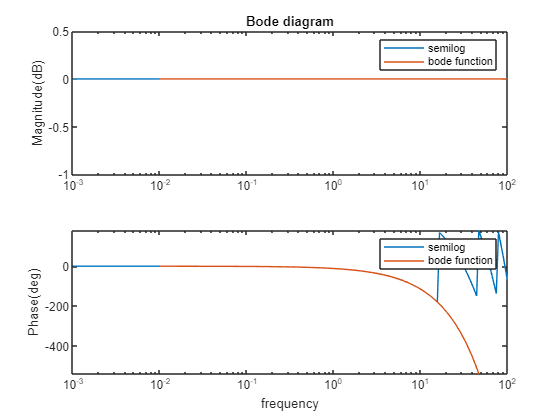

s = tf("s");
Gb = exp(-0.2*s);
syms s
Gl = @(s) exp(-0.2*s);
Gl = Gl(1i*w);

[mag,pha,wout]=bode(Gb,{0.01 100});

Glm = 20*log10(abs(Gl));
Glp = atan2d(imag(Gl),real(Gl));

magi = 20*log10(mag(1,1,1));
for i=2:size(mag,3)
    magi = [magi,20*log10(mag(1,1,i))];
end
phai = pha(1,1,1);
for i=2:size(pha,3)
    phai = [phai,pha(1,1,i)];
end

subplot(2,1,1)
semilogx(w,Glm,wout,magi)
ylim([-1 0.5])
ylabel("Magnitude(dB)")
title("Bode diagram")
legend("semilog","bode function")

subplot(2,1,2)
semilogx(w,Glp,wout,phai)
xlabel("frequency")
ylabel("Phase(deg)")
legend("semilog","bode function")
ylim([-540 180])

## d)

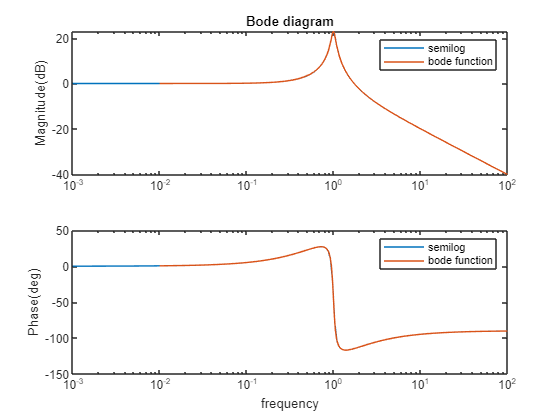

s = tf("s");
Gb = (s+1)/(s^2+0.1*s+1);
syms s
Gl = @(s) (s+1)./(s.^2+0.1*s+1);
Gl = Gl(1i*w);

[mag,pha,wout]=bode(Gb);

Glm = 20*log10(abs(Gl));
Glp = atan2d(imag(Gl),real(Gl));

magi = 20*log10(mag(1,1,1));
for i=2:size(mag,3)
    magi = [magi,20*log10(mag(1,1,i))];
end
phai = pha(1,1,1);
for i=2:size(pha,3)
    phai = [phai,pha(1,1,i)];
end

subplot(2,1,1)
semilogx(w,Glm,wout,magi)
ylabel("Magnitude(dB)")
title("Bode diagram")
legend("semilog","bode function")

subplot(2,1,2)
semilogx(w,Glp,wout,phai)
xlabel("frequency")
ylabel("Phase(deg)")
legend("semilog","bode function")

## e)

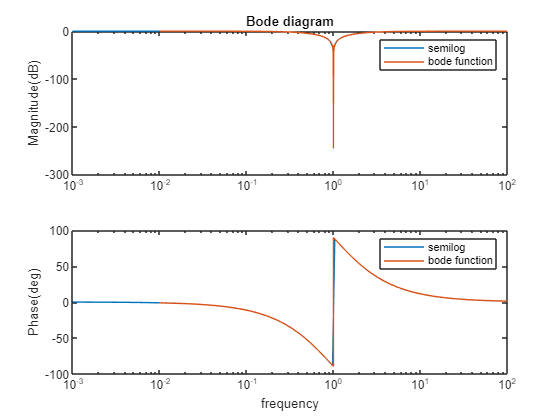

s = tf("s");
Gb = (s^2+1)/(s+1)^2;
syms s
Gl = @(s) (s.^2+1)./(s+1).^2;
Gl = Gl(1i*w);

[mag,pha,wout]=bode(Gb);

Glm = 20*log10(abs(Gl));
Glp = atan2d(imag(Gl),real(Gl));

magi = 20*log10(mag(1,1,1));
for i=2:size(mag,3)
    magi = [magi,20*log10(mag(1,1,i))];
end
phai = pha(1,1,1);
for i=2:size(pha,3)
    phai = [phai,pha(1,1,i)];
end

subplot(2,1,1)
semilogx(w,Glm,wout,magi)
ylabel("Magnitude(dB)")
title("Bode diagram")
legend("semilog","bode function")

subplot(2,1,2)
semilogx(w,Glp,wout,phai)
xlabel("frequency")
ylabel("Phase(deg)")
legend("semilog","bode function")

clc 
clear all
close all

# 8 Convolution

## a)

Tmax = 15;
Samples = 1000;
T  = linspace(-1,Tmax,Samples);
TY = linspace(-1,2*Tmax,2*Samples-1);
syms t
h1 = piecewise( t<2,0 , 2<=t<3,1 , ...
     3<=t<4,-2 ,4<=t<5,1 , t>=5,0 ) 

$$h1 = \left\{ \begin{array}{cl} 0 & \text{ if }t<2\\ 1 & \text{ if }t\in \left[2,3\right)\\ -2 & \text{ if }t\in \left[3,4\right)\\ 1 & \text{ if }t\in \left[4,5\right)\\ 0 & \text{ if }5\leq t \end{array}\right.$$

u1 =  piecewise(t<0,0 , 0<=t<7,1 , t>=7,0)

$$u1 = \left\{ \begin{array}{cl} 0 & \text{ if }t<0\\ 1 & \text{ if }t\in \left[0,7\right)\\ 0 & \text{ if }7\leq t \end{array}\right.$$

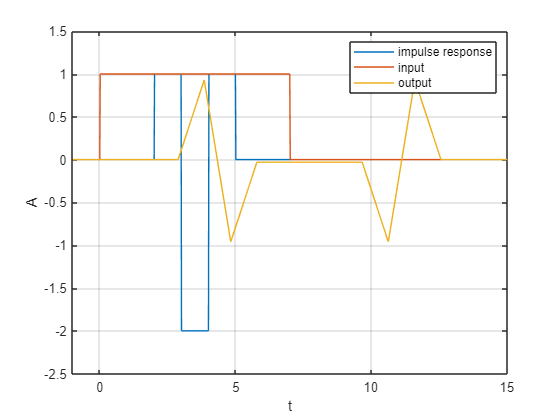

ht = eval(subs(h1,t,T));

ut = eval(subs(u1,t,T));
yt = Tmax/Samples*conv(ht,ut);

plot(T,ht,T,ut,TY,yt)
ylim([-2.5 1.5])
xlim([-1 15])
grid on
legend("impulse response","input","output")
xlabel("t")
ylabel("A")

## b)

Tmax = 6;
Samples = 1000;
T  = linspace(-1,Tmax,Samples);
TY = linspace(-1,2*Tmax,2*Samples-1);
syms t
h2 = piecewise( t<0,0 , 0<=t<1,t , ...
     1<=t<2,1 ,2<=t<3,3-t , t>=3,0 ) 

$$h2 = \left\{ \begin{array}{cl} 0 & \text{ if }t<0\\ t & \text{ if }t\in \left[0,1\right)\\ 1 & \text{ if }t\in \left[1,2\right)\\ 3-t & \text{ if }t\in \left[2,3\right)\\ 0 & \text{ if }3\leq t \end{array}\right.$$

u2 =  piecewise(t<0,0 , 0<=t<1,1 , t>=1,0)

$$u2 = \left\{ \begin{array}{cl} 0 & \text{ if }t<0\\ 1 & \text{ if }t\in \left[0,1\right)\\ 0 & \text{ if }1\leq t \end{array}\right.$$

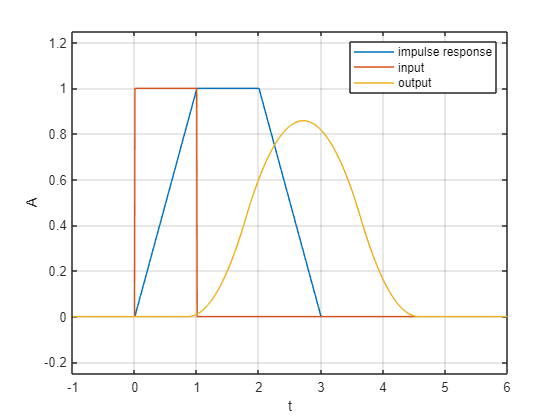

ht = eval(subs(h2,t,T));

ut = eval(subs(u2,t,T));
yt = Tmax/Samples*conv(ht,ut);

plot(T,ht,T,ut,TY,yt)
ylim([-0.25 1.25])
xlim([-1 6])
grid on
legend("impulse response","input","output")
xlabel("t")
ylabel("A")

## c)

Tmax = 5;
Samples = 1000;
T  = linspace(-1,Tmax,Samples);
TY = linspace(-1,2*Tmax,2*Samples-1);
syms t
h3 = piecewise( t<0,0 , 0<=t<1,t , ...
     1<=t<2,1-t , t>=2,0 ) 

$$h3 = \left\{ \begin{array}{cl} 0 & \text{ if }t<0\\ t & \text{ if }t\in \left[0,1\right)\\ 1-t & \text{ if }t\in \left[1,2\right)\\ 0 & \text{ if }2\leq t \end{array}\right.$$

u3 =  piecewise(t<1,0 , 1<=t<2,sin(pi*t) , t>=2,0)

$$u3 = \left\{ \begin{array}{cl} 0 & \text{ if }t<1\\ \sin\left(\pi \,t\right) & \text{ if }t\in \left[1,2\right)\\ 0 & \text{ if }2\leq t \end{array}\right.$$

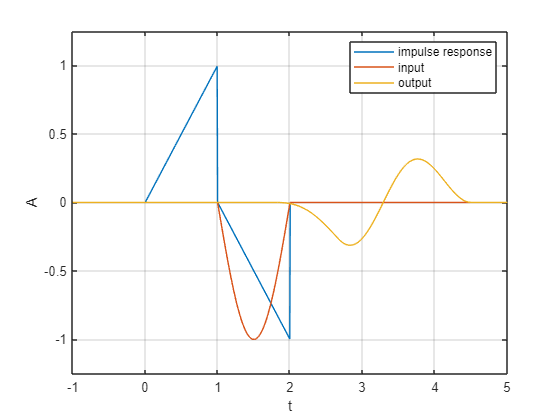


ht = eval(subs(h3,t,T));

ut = eval(subs(u3,t,T));
yt = Tmax/Samples*conv(ht,ut);

plot(T,ht,T,ut,TY,yt)
ylim([-1.25 1.25])
xlim([-1 5])
grid on
legend("impulse response","input","output")
xlabel("t")
ylabel("A")

clc 
clear all
close all

# 9 Impulse Response Truncation

## a)


$$\frac{1-e^{-\frac{T_s }{2}} e^{-T_s s} }{2s+1}=\frac{1}{2s+1}-\frac{e^{-\frac{T_s }{2}} e^{-T_s s} }{2s+1}\Rightarrow \;{0\ldotp 5e}^{-0\ldotp 5t} u\left(t\right)-0\ldotp 5e^{-\frac{T_S }{2}} e^{-0\ldotp 5\left(t-T_S \right)} u\left(t-T_s \right)=\;{0\ldotp 5e}^{-0\ldotp 5t} u\left(t\right)-0\ldotp 5e^{-0\ldotp 5\left(t\right)} u\left(t-T_s \right)=\left\lbrace \begin{array}{ll}
t<T_s  & \;{0\ldotp 5e}^{-0\ldotp 5t} u\left(t\right)\\
t\ge T_s  & 0
\end{array}\right.$$


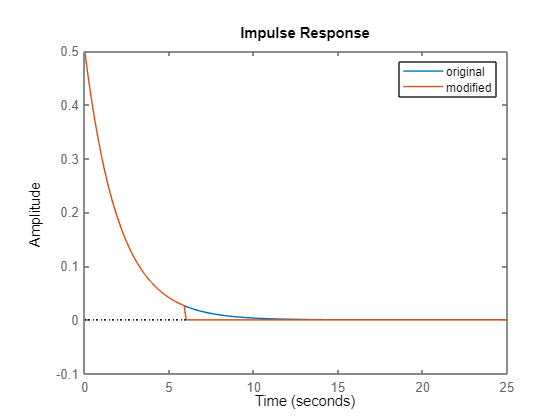

s = tf("s");
Ts = 6;
T1 = 1/(2*s+1);
T2 = (1-exp(-Ts/2)*exp(-Ts*s))/(2*s+1);
impulse(T1,T2)
legend("original","modified")

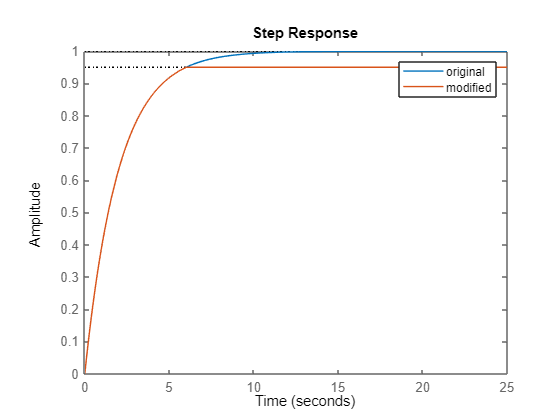

step(T1,T2)
legend("original","modified")

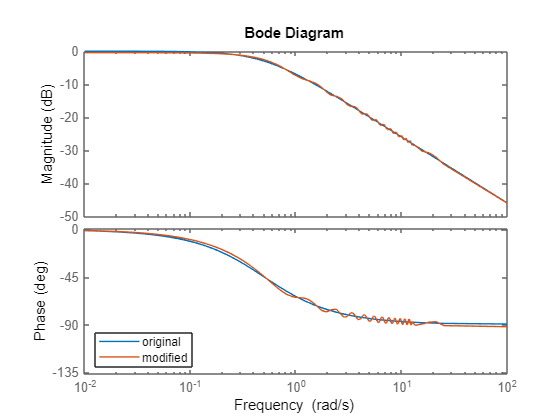

bode(T1,T2)
legend("original","modified",'Location','southwest')

## b)


$$\frac{1}{s^2 +s+1}\longrightarrow \frac{2}{\sqrt{3}}e^{-0\ldotp 5t} \sin \left(\frac{\sqrt{3}}{2}t\right)u\left(t\right)$$


modified sestem:


$$\begin{array}{l}
\frac{2}{\sqrt{3}}e^{-0\ldotp 5t} \sin \left(\frac{\sqrt{3}}{2}t\right)\left(u\left(t\right)-u\left(t-T_s \right)\right)\\
\longrightarrow \frac{1}{s^2 +s+1}-\frac{e^{-T_s \left(s+0\ldotp 5\right)} \left(\left(1\ldotp 1547s+0\ldotp 57735\right)\sin \left(\frac{\sqrt{3}}{2}T_S \right)+\cos \left(\frac{\sqrt{3}}{2}T_s \right)\right)}{s^2 +s+1}
\end{array}$$


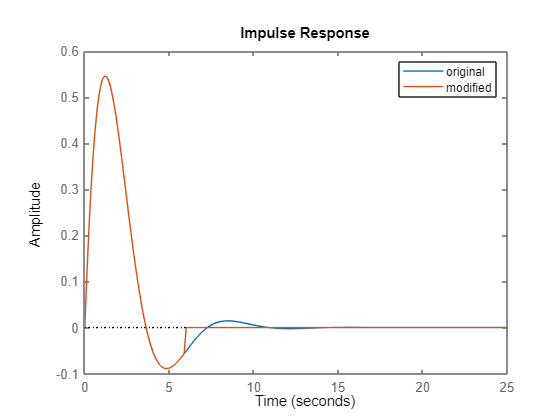

s = tf("s");
Ts = 6; 
T1 = 1/(s^2+s+1);
T2 = (1 - ( exp(-Ts*s)*exp(-Ts/2) *(((1.1547*s+0.57735)*sin(0.5*sqrt(3)*Ts))+cos(0.5*sqrt(3)*Ts) ) ) )/(s^2+s+1);
impulse(T1,T2)
legend("original","modified")

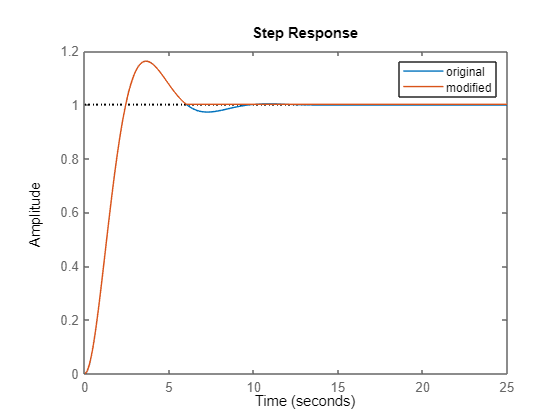

step(T1,T2)
legend("original","modified")

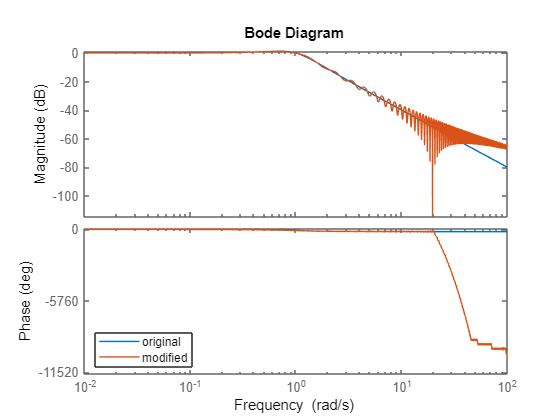

bode(T1,T2)
legend("original","modified",'Location','southwest')
xlim([0.01 100])

# 10 Chrip Signal and Frequency Response

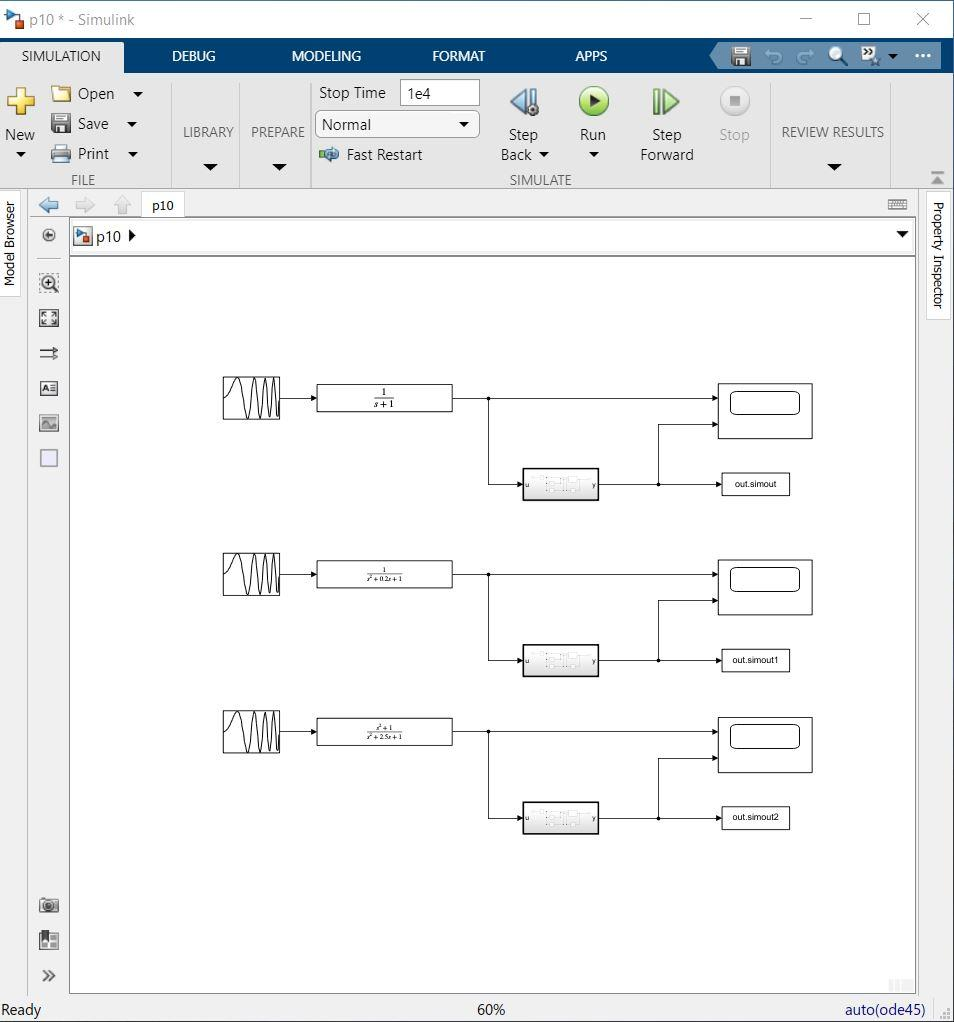

## a)

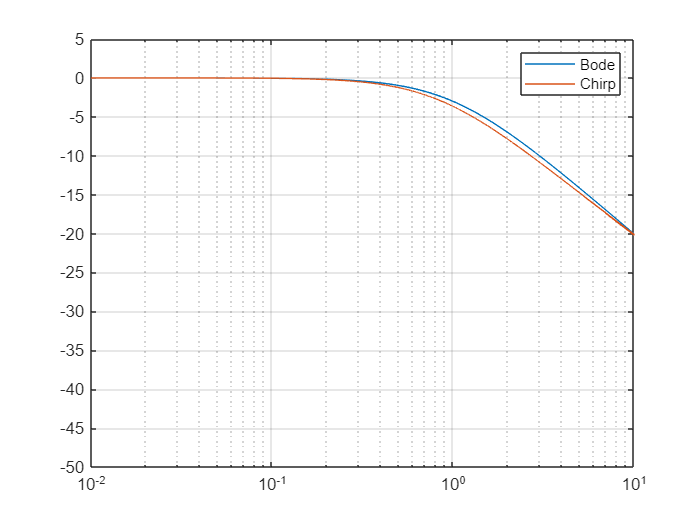

s = tf("s");
G1 = 1/(s+1);

envelope = out.simout.Data;
w = linspace(0.01,10,length(envelope));
h = reshape(bode(G1,w),size(w));
figure();
semilogx(w,20*log10(h))
hold on
semilogx(w,20*log10(envelope));
grid on
ylim([-50 5]);
legend({'Bode',"Chirp"});

## b)

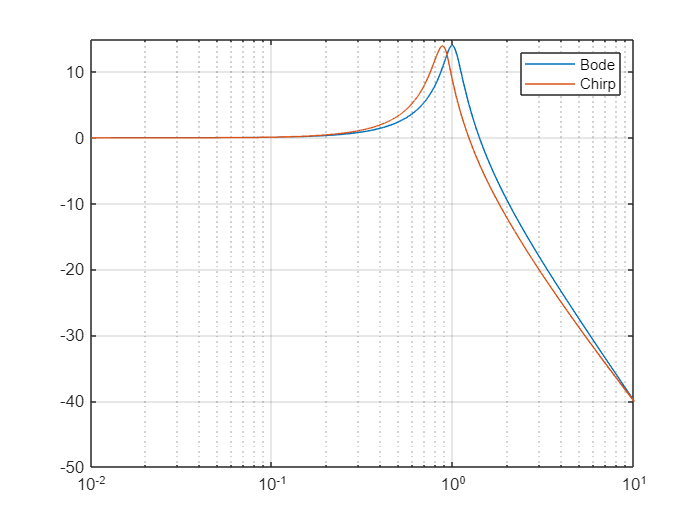

s = tf("s");
G1 = 1/(s^2+0.2*s+1);

envelope = out.simout1.Data;
w = linspace(0.01,10,length(envelope));
h = reshape(bode(G1,w),size(w));
figure();
semilogx(w,20*log10(h))
hold on
semilogx(w,20*log10(envelope));
grid on
ylim([-50 15]);
legend({'Bode',"Chirp"});

## c)

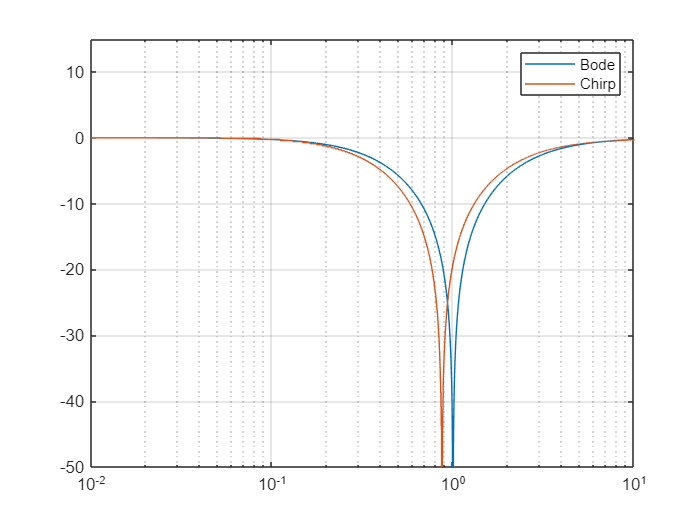

s = tf("s");
G1 = (s^2+1)/(s^2+2.5*s+1);

envelope = out.simout2.Data;
w = linspace(0.01,10,length(envelope));
h = reshape(bode(G1,w),size(w));
figure();
semilogx(w,20*log10(h))
hold on
semilogx(w,20*log10(envelope));
grid on
ylim([-50 15]);
legend({'Bode',"Chirp"});

# 11 Simulink System Implementation using Impulse Response